# Perform Co-Simulation between Simulink and Gazebo

This example shows how to set up a synchronized simulation between Simulink™ and Gazebo to send commands and receive data from Gazebo.

## Setup Gazebo Simulation Environment

For this example, use your own Linux environment with Gazebo or download the provided [Virtual Machine with ROS and Gazebo](https://www.mathworks.com/ros_vm_install/v6). In the virtual machine (VM), the required Gazebo plugin is located in `/home/user/src/GazeboPlugin. `

For more information on the Linux VM and the requirements for setting up your own Linux environment with Gazebo, see [Gazebo Simulation Environment Requirements and Limitations](docid:robotics_ug#mw_7120a9da-7ec9-48a5-9231-2f91166f07da).

In the VM settings disable Accelerate 3D graphics. In VM settings, VM > Settings > Hardware > Display, disable Accelerate 3D graphics.

If using your own Linux environment, follow the steps in Install Gazebo Plugin Manually. Otherwise, go to Launch Gazebo Simulation Environment.

### Install Gazebo Plugin Manually

Obtain the plugin source code as a zip package. This function creates a folder called `GazeboPlugin` in your current working directory and compresses it as `GazeboPlugin.zip`.

packageGazeboPlugin

Copy the `GazeboPlugin.zip` to your Linux machine that meets the following requirement:

Unzip the package on your Linux platform, for this example we unpack to `/home/user/src/GazeboPlugin`.

Run these commands in the terminal to compile the plugin.

If the `build` folder already exists, remove it.

Install the plugin.

The plugin location is `/home/user/src/GazeboPlugin/export/lib/libGazeboCoSimPlugin.so`.

Remove the generated plugin from host computer.

if exist('GazeboPlugin', 'dir')
    rmdir('GazeboPlugin', 's');
end

if exist('GazeboPlugin.zip', 'file')
    delete('GazeboPlugin.zip');
end

## Launch Gazebo Simulation Environment

Open a terminal in the VM or your own Linux operating system, run the following commands to launch the Gazebo simulator.

These commands launch a Gazebo simulator with:

- Two laser range finders: `hokuyo0` and `hokuyo1`

- Two RGB cameras: `camera0` and `camera1`

- Two depth cameras: `depth_camera0` and` depth_camera1`

- Two IMU sensors: `imu0` and `imu1`

- Unit box model: `unit_box`

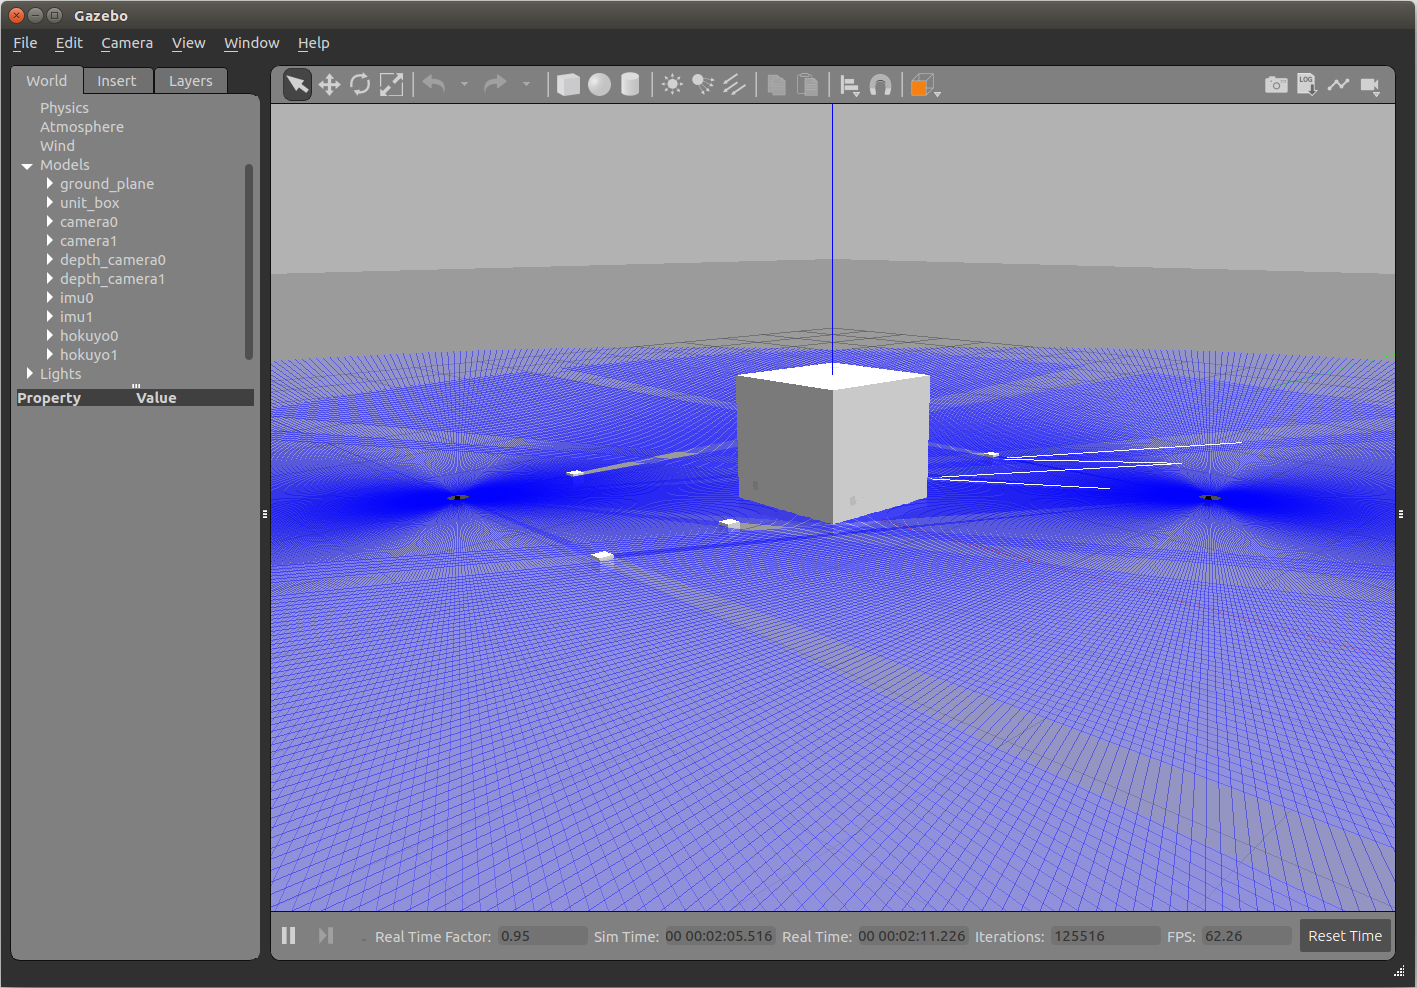

The `multiSensorPluginTest.world` is located in `/home/user/src/GazeboPlugin/world` folder. This world file includes the Gazebo plugin for co-simulation with Simulink using the following lines in its .`xml` body:

The filename field must be pointing to the location of the compiled Gazebo plugin. This path can be relative to the location Gazebo itself is launched, or you could add it to the Gazebo plugin search path by Gaze

running:

## Configure Gazebo Co-Simulation

Open the `performCoSimulationWithGazebo` model, wcdhich demonstrates how to receive sensor data from these simulated sensors and how to actuate the unit box model from Simulink.

open_system("performCoSimulationWithGazebo")

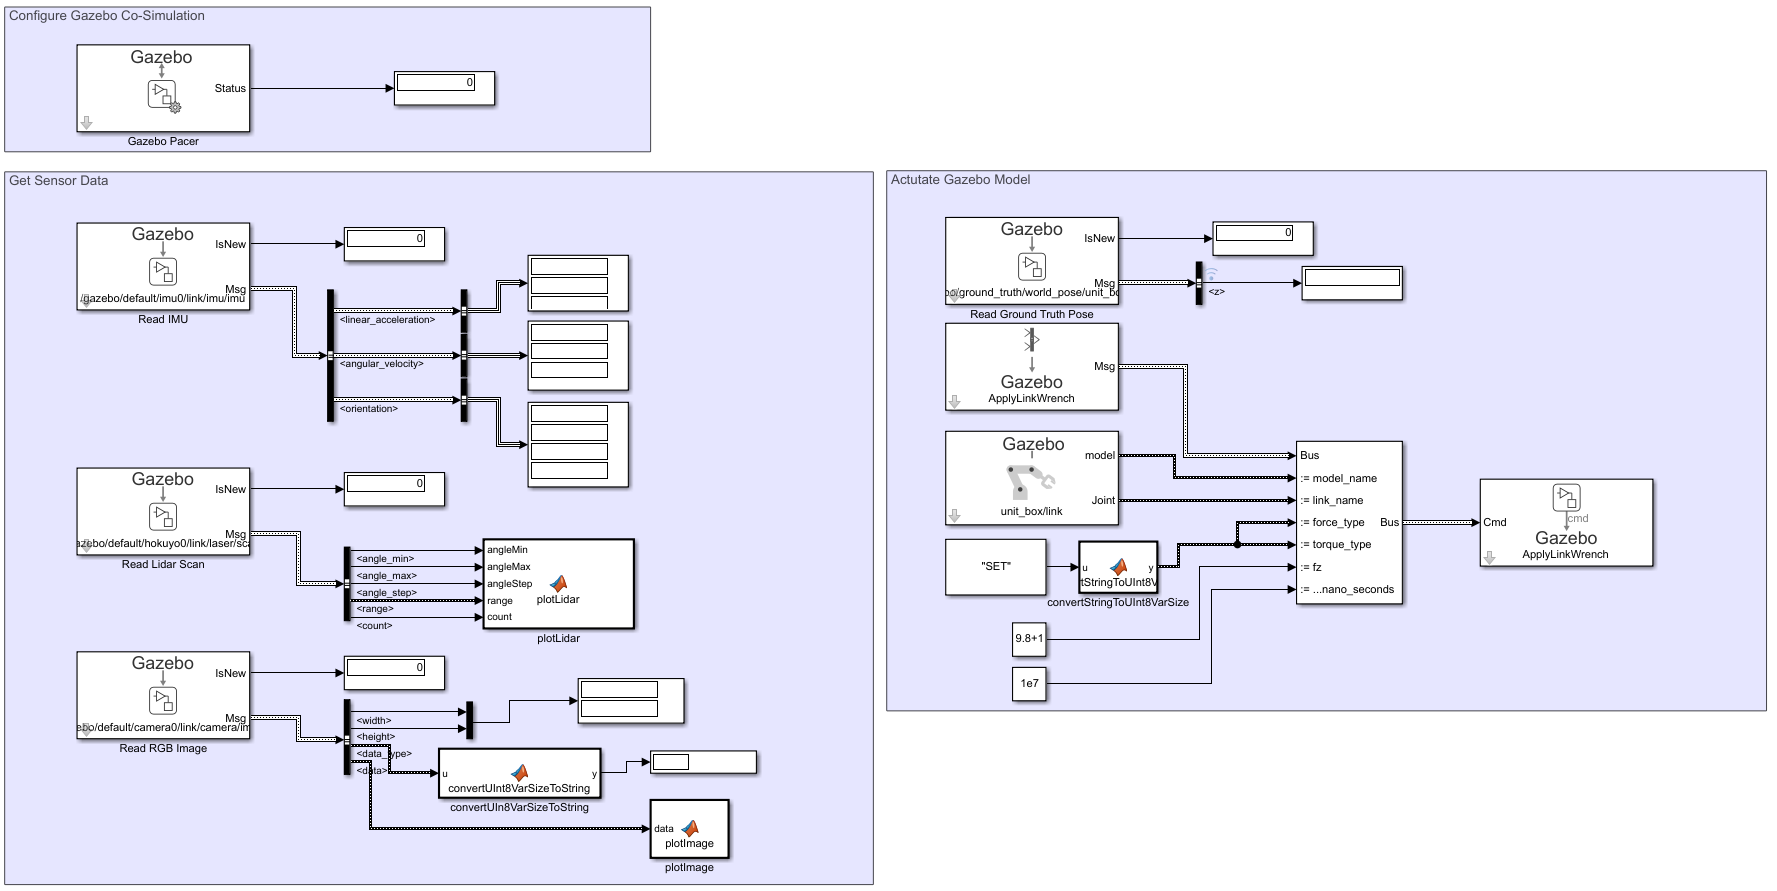

Before simulating the model, configure Gazebo Co-Simulation using **Gazebo Pacer** block:

hilite_system('performCoSimulationWithGazebo/Gazebo Pacer')

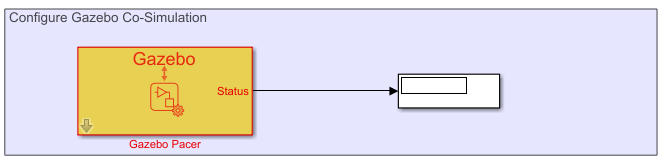

Open the block and click the **Configure Gazebo network and simulation settings** link.

open_system('performCoSimulationWithGazebo/Gazebo Pacer')

 In the **Network Address** drop down, select `Custom`. Enter the IP address of your Linux machine. The default **Port** for Gazebo is `14581`. Set **Response timeout** to 10 seconds.

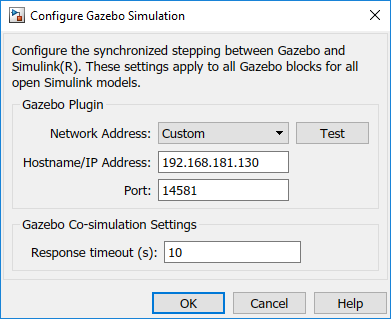

Click the **Test** button to test the connection to the running Gazebo simulator.

## Get Sensor Data

Use the **Gazebo Read** block to obtain data on specific topics from three sensors:

-  IMU, `/gazebo/default/imu0/link/imu/imu`

- Lidar Scan, `/gazebo/default/hokuyo0/link/laser/scan`

- RGB camera, `/gazebo/default/camera0/link/camera/image`

Display the IMU readings and visualize the Lidar Scan and RGB Image using MATLAB® function blocks.

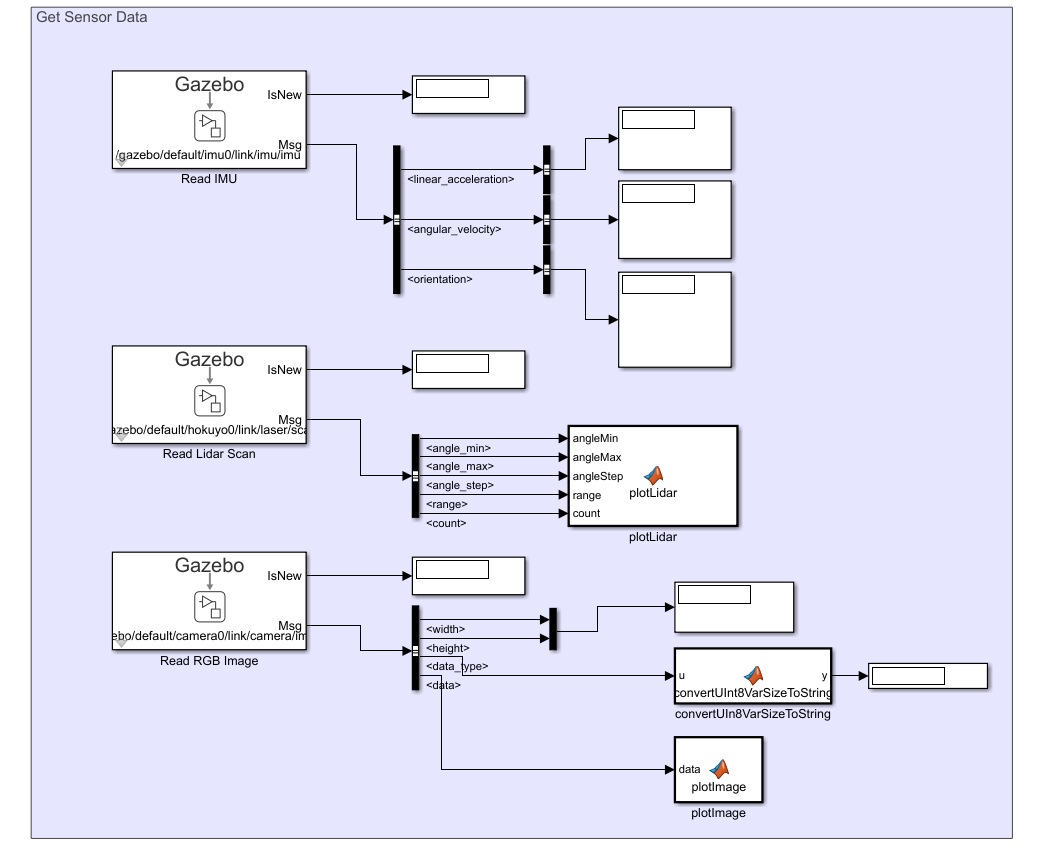

## Actuate Gazebo Model

Use the **Gazebo Apply Command** block to apply a constant force in the *z*-direction to the unit box that results in an acceleration of 1 $m/s^2$. Create a blank `ApplyLinkWrench` message using **Gazebo Blank Message**. Specify elements of the message to apply the force to the `unit_box/link` entity using the **Bus Assignment** block. Use **Gazebo Read** to output the ground truth pose of the box. The displacement of the box over a 1 second period should be close to 0.5 meters. 

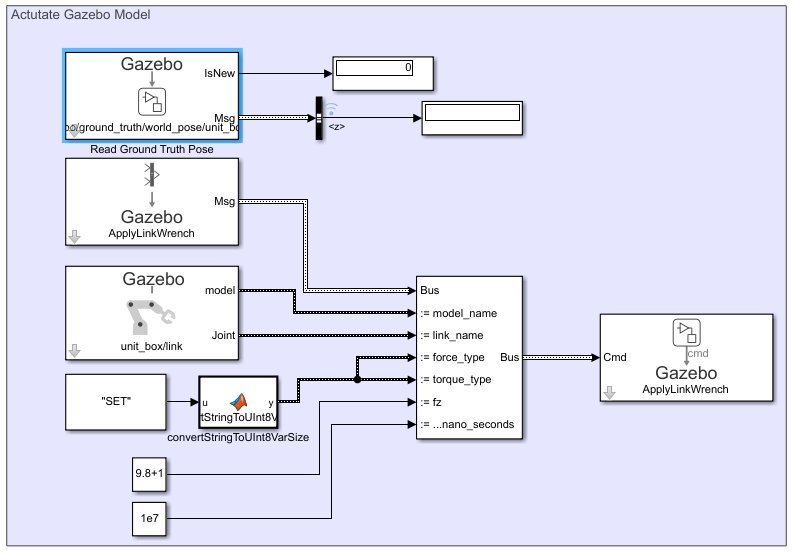

## Perform Co-Simulation

To start co-simulation,click **Run**. You can also step the simulation using **Step Forward**. **Step Back** is not supported during co-simulation.

While the simulation is running, notice that Gazebo simulator and Simulink time are synchronized. 

This model visualizes the Gazebo sensor data using MATLAB function block and MATLAB plotting functionalities. Here is a snapshot of the image data obtained from Gazebo camera:

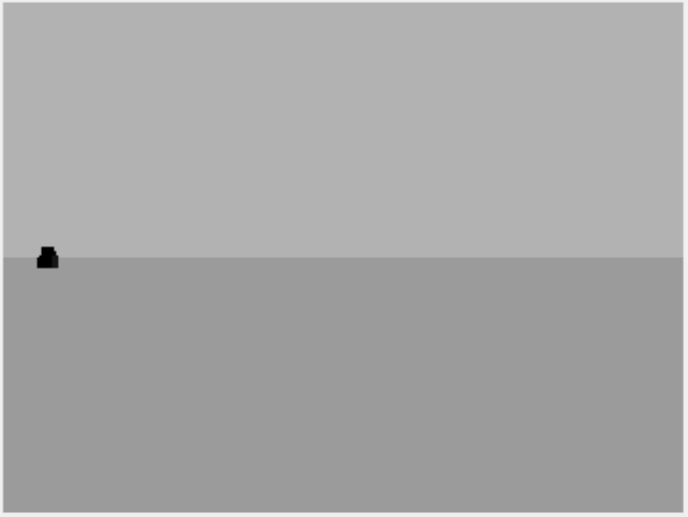

Here is a snapshot of the lidar scan image:

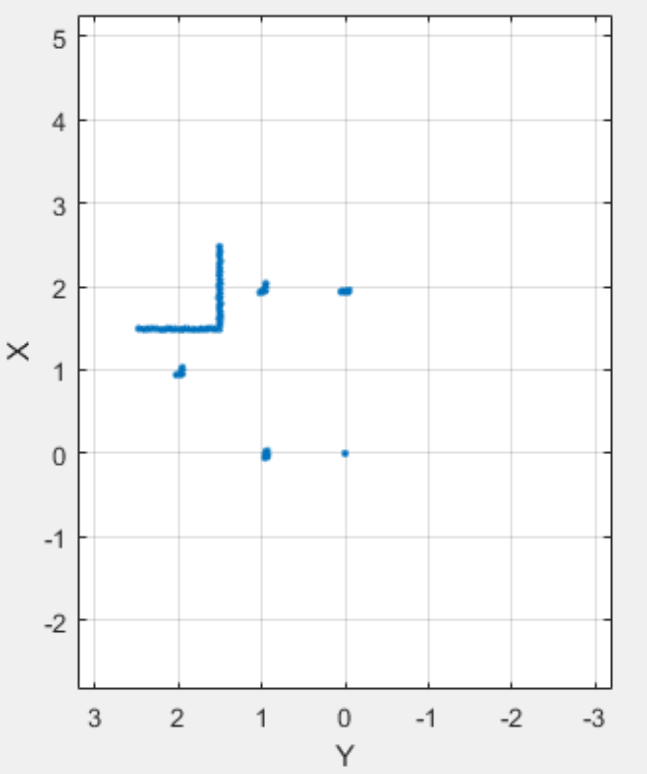

The time-plot of the position of the unit box block in *z*-direction can be viewed using **Data Inspector**. The block tracks a parabolic shape due to the constant acceleration over time.

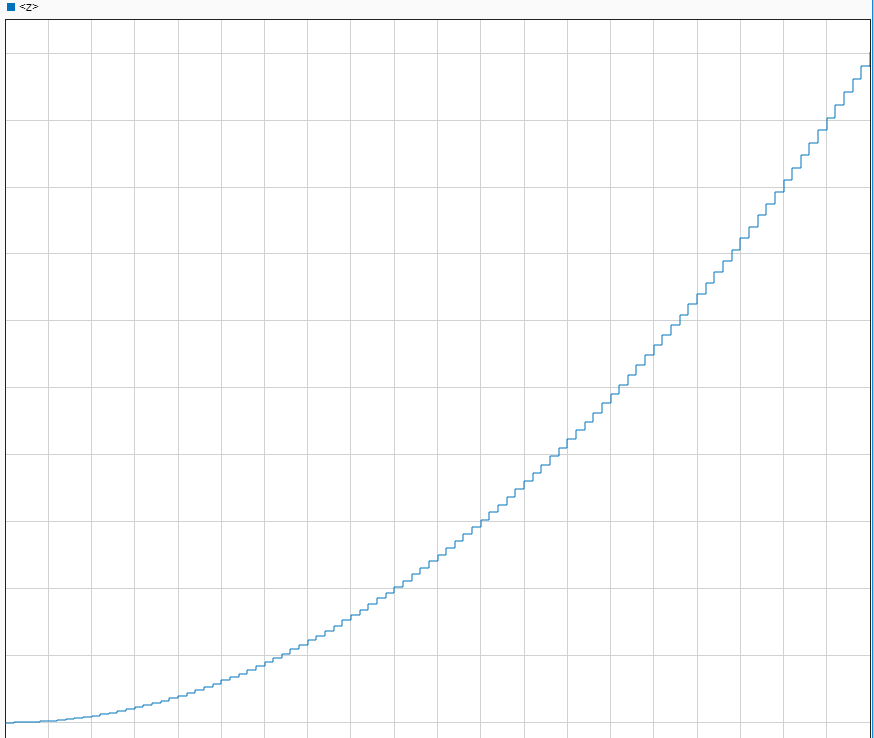

The position of the unit box at the end of simulation is 1.001, leading to a 0.5001 displacement, which is slightly different from the expected value of 0.5. This is due to the error of the Gazebo physics engine. Make the max step size in the Gazebo physics engine smaller to reduce this error.

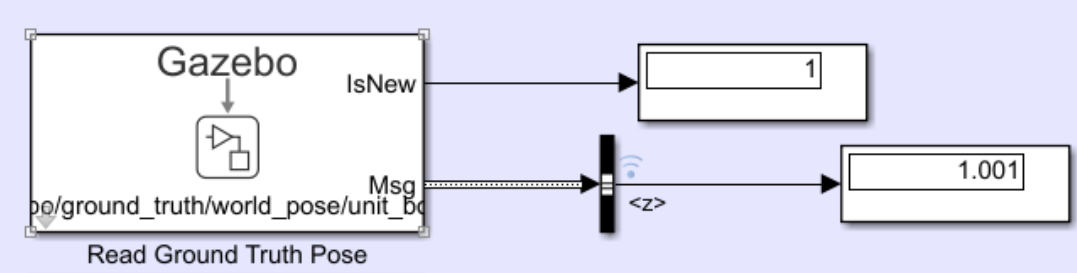

## Time Synchronization

During co-simulation, you can pause Simulink and the Gazebo Simulator at any time using **Pause**

**Note:** Gazebo pauses one time step ahead of the simulation.

    

This is due to the following co-simulation time sequence:

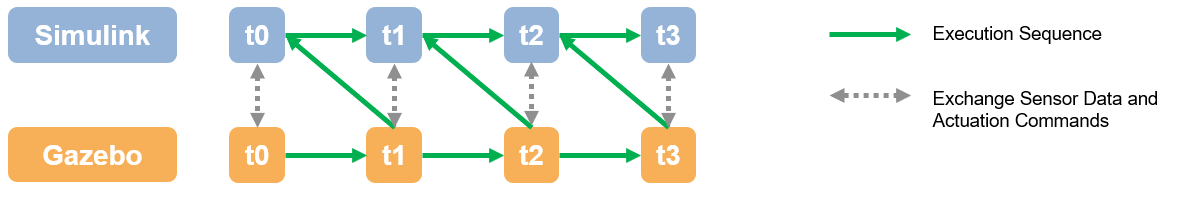

Sensor data and actuation commands are exchanged at the correct time step. The execution chooses to step Gazebo first, then Simulink. The simulation execution is still on the *t+1*, Simulink just stays on the previous step time until you resume the model.

## Next Steps

- [Control a Differential Drive Robot in Simulink and Gazebo](docid:robotics_ug.mw_ea28eff9-a4e4-4c5c-9a96-de7a21e4ed4d)

*Copyright 2019 The MathWorks, Inc.*